# Code commenting

A colleague has recently left your development team at work. They were a great coder, but notoriously bad at commenting their work. Your boss has asked you to go through one of their scripts which contains some work on classifying hand-written letter shapes, and add comments that will help the rest of your team understand what's going on. You should add comments in your own words and you should prioritise clearly explaining what is going on to colleagues who may not have much experience of Machine Learning. It's fine if your comments go over more than one line.

The steps you should comment on, and the number of marks available for each comment are indicated below:

% add your comment here [1 mark]: 
% Clears all variables from current
% workspace and then reads data from letterdata.csv into the table with the
% name 'data' for use later in the script.
clear all;
data = readtable('letterdata.csv');

% add your comment here [1 mark]: 
% Re-seed matlabs random number generator
% with a value of 1, this means the set of random numbers generated will be the same each time, this is so results can be cross-compared and discussed
rng(1);

% add your comment here [1 mark]: 
% Shuffles the rows of the table by indexing the 'data' table using a random permutation of integers from 1 to the size of the table and stores
% the shuffled table in 'data_shuffled', the data needs to be shuffled as
% datasets are often sorted before being exported, if we were to split up
% sorted data into training and testing sets then both new sets would
% contain unrepresentative data 
data_shuffled = data(randperm(size(data,1)), :);

% add your comment here [2 marks]: 
% Store the first 16000 rows of the table
% in 'data_test' and everything after the first 16000 in 'data_train', the
% data is split up like this so some of the data can be used to train the
% classifier and some to test the classifier and make predictions, the
% 'horizontal split' method is used to avoid overfitting the data
data_test = data_shuffled(1:1:16000, :);
data_train = data_shuffled(16001:1:end, :);

% add your comment here [2 marks]: 
% Splits the labels of the test data up
% into a categorical array also stores the data in a new table 'test_examples' and removes
% the labels from that table. The labels are split from the data as we do
% not need the original ones when testing our classifier, however we will
% need the original labels when evaluating the classifiers performance
test_labels = categorical(data_test{:,'letter'});
test_examples = data_test;
test_examples(:,'letter') = [];

% add your comment here [2 marks]: 
% Splits the labels of the training data up
% into a categorical array (a categorical array is used so that we can call in-built functions such as 'mode()' on the data later on) also stores the data in a new table 'train_examples' and removes
% the labels from that table. The labels are split from the data as the
% labels are not being used when trying to make a prediction from the data,
% they are only used when assinging the test data a label. (uses the most common label of the test data k nearest neighbours)
train_labels = categorical(data_train{:,'letter'});
train_examples = data_train;
train_examples(:,'letter') = [];

% add your comment here [2 marks]: 
% calls the fitcknn() function (used to train the classifier)
% parsing the table of training examples and the
% categorical array of labels, no k value is given so the default '1' is
% used meaning that only the first nearest neighbour will be used when making a prediction so the test data will be assigned the same label as the nearest neighbour to it, also stadardize is set to true this means  the values of each
% feature will be re-scaled to make sure they lie within a similar range.
% The structure 'm' (model) is returned from the function, this stores all
% the information about the classifier
m = fitcknn(train_examples, train_labels, 'Standardize', true);

% add your comment here [1 mark]: 
% The predict() function is called giving the classifier information and
% the test examples as its parameters, this is so that the distance can be
% calculated between each test example and all of the training examples
% (m.train_examples) and then a prediction can be made for each test
% example by taking the most commong label from its nearest neighbours,
% all of these predictions are returned as an array 'predictions' from the
% function
predictions = predict(m, test_examples);

% add your comment here [1 mark]: 
% Build a confusion matrix using the
% categorical array of test labels and the predictions from the test
% examples, the confusion matrix shows all the correct predictions down the
% diagonal and incorrect predictions surrounding the diagonal, the value represents how many times that prediction was made.
[c,order] = confusionmat(test_labels, predictions)

c =    615     2     1     2     0     1     0     0     0     4     0     0     3     0     1     0     2     0     0     1     2     0     0     1     0     0
     0   531     0     7    12     2     0    10     0     0     2     0     2     1     1     0     0    28     4     0     0     8     0     1     0     1
     0     0   519     0     7     0    17     1     0     0     0     1     0     0    16     0     4     0     1     0     1     0     1     0     0     0
     0    16     0   566     1     1     2    14     0     1     4     0     0     3     6     1     2    10     2     2     0     1     1     2     0     5
     0     7    11     0   541     3     8     3     0     0     6     4     0     0     0     1     1     0     8     2     0     1     1     9     0    14
     1     0     1     1     4   541     1     2     4     0     1     1     0     2     0    24     0     1     7    16     0     4     0     0     2     1
     0     6     3     6    12     1   548     4     0

order = 26×1 categorical array
     A 
     B 
     C 
     D 
     E 
     F 
     G 
     H 
     I 
     J 
     K 
     L 
     M 
     N 
     O 
     P 
     Q 
     R 
     S 
     T 
     U 
     V 
     W 
     X 
     Y 
     Z 



% add your comment here [2 marks]: 
% Calculates the overall classification
% accuracy using the values given by the confusion matrix

% Calculates the overall classification
% accuracy using the values given by the confusion matrix as the total number of correct classifications divided by the total number of classifications made
p = sum(diag(c)) / sum(c(:))

p = 0.8904


% add your comment here [2 marks]: 
% Remove the diagonal from the confusion matrix to
% create a matrix of all the errors, create figure window and set its color
% map to 'gray' then display errors as image with scaled colors.
% visualising error, the lighter coloured squares represent the more common
% errors, the darker squares represent less common errors and the black
% squares represent no error.
c_errors = c;

c_errors =    615     2     1     2     0     1     0     0     0     4     0     0     3     0     1     0     2     0     0     1     2     0     0     1     0     0
     0   531     0     7    12     2     0    10     0     0     2     0     2     1     1     0     0    28     4     0     0     8     0     1     0     1
     0     0   519     0     7     0    17     1     0     0     0     1     0     0    16     0     4     0     1     0     1     0     1     0     0     0
     0    16     0   566     1     1     2    14     0     1     4     0     0     3     6     1     2    10     2     2     0     1     1     2     0     5
     0     7    11     0   541     3     8     3     0     0     6     4     0     0     0     1     1     0     8     2     0     1     1     9     0    14
     1     0     1     1     4   541     1     2     4     0     1     1     0     2     0    24     0     1     7    16     0     4     0     0     2     1
     0     6     3     6    12     1   548     

c_errors = c_errors - diag(diag(c_errors));

c_errors =      0     2     1     2     0     1     0     0     0     4     0     0     3     0     1     0     2     0     0     1     2     0     0     1     0     0
     0     0     0     7    12     2     0    10     0     0     2     0     2     1     1     0     0    28     4     0     0     8     0     1     0     1
     0     0     0     0     7     0    17     1     0     0     0     1     0     0    16     0     4     0     1     0     1     0     1     0     0     0
     0    16     0     0     1     1     2    14     0     1     4     0     0     3     6     1     2    10     2     2     0     1     1     2     0     5
     0     7    11     0     0     3     8     3     0     0     6     4     0     0     0     1     1     0     8     2     0     1     1     9     0    14
     1     0     1     1     4     0     1     2     4     0     1     1     0     2     0    24     0     1     7    16     0     4     0     0     2     1
     0     6     3     6    12     1     0     

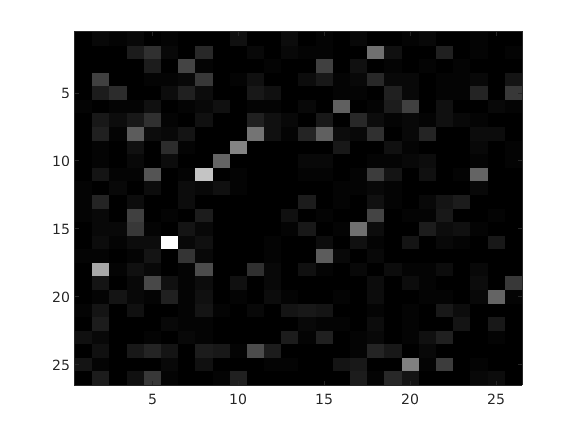

figure;
colormap('gray');
imagesc(c_errors);


% add your comment here [3 marks]: 
% Store the max value index of the errors matrix (this is the index of the most common error in the matrix)
% in m, then store the row (in var 'i') and column (in var 'j') of index m
% print which label was mistaken for which for the most common error.
[~, m] = max(c_errors(:));
[i,j] = ind2sub(size(c_errors), m);
fprintf('%s mistaken for %s\n', order(i), order(j));

P mistaken for F


[Total: 20 marks]